Set variables

l3=1;
l5=2;
theta1=0;
theta2=45;



theta1=pi/180*theta1;
theta2=pi/180*theta2;

create vectors

l3=[l3, 0, 0]'

l3 =      1
     0
     0


l5=[l5, 0, 0]'

l5 =      2
     0
     0


r5=1

r5 = 1

plot rotation

W1pos=zeros(100,3);
W2pos=zeros(100,3);
cpos=zeros(100,3);
for i = 1:100
    theta1=i*2*pi/100;
    theta2=0.02;
    [p2,~,~,p5,p6] = calculatePosition(theta1, theta2, l3, l5, r5);
    W1pos(i,:)=p5;
    W2pos(i,:)=p6;
    cpos(i,:)=p2;
end


W1pos

W1pos =     0.0628         0         0
    0.1257         0         0
    0.1885         0         0
    0.2513         0         0
    0.3142         0         0
    0.3770         0         0
    0.4398         0         0
    0.5027         0         0
    0.5655         0         0
    0.6283         0         0


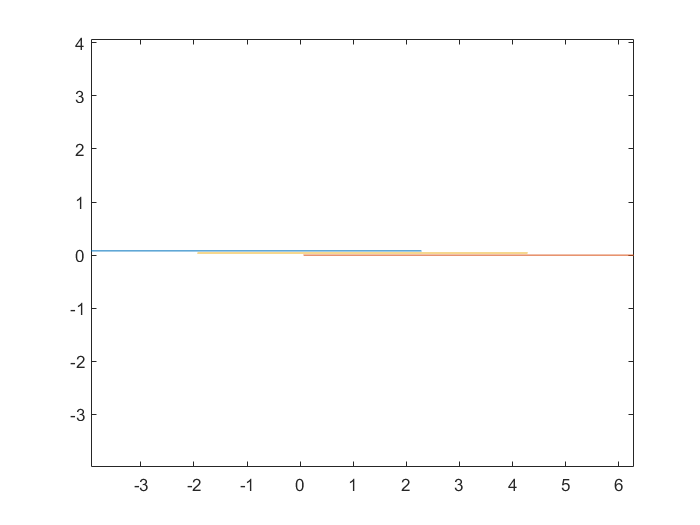

plot(W2pos(:,1), W2pos(:,2))
hold on
plot(W1pos(:,1), W1pos(:,2))
plot(cpos(:,1), cpos(:,2))
axis equal


f3 = [0, 2, 0]'

f3 =      0
     2
     0


l3 = [1, 0, 0]'

l3 =      1
     0
     0


l3*f3'

ans =      0     2     0
     0     0     0
     0     0     0


cross(l3, f3)

ans =      0
     0
     2



syms m [1 7] %masses of elements
syms I [1 7] %moments of inertia
syms F2 [3,1] matrix %forces applied to frame from element
syms F3 [3,1] matrix
syms F4 [3,1] matrix
syms F5 [3,1] matrix
syms F6 [3,1] matrix
syms F7 [3,1] matrix
syms 

function [p2, p3, p4, p5, p6] = calculatePosition(theta1, theta2, l3, l5, r5)

%Roll
s=[r5*theta1, 0 ,0]';


%Rotation vector
Rz=[cos(theta2), sin(theta2), 0;
    -sin(theta2), cos(theta2), 0;
    0, 0, 1];
l3p= Rz*l3;
l5p= Rz*l5;



%ground condition
if (sin(theta2)>0)
    %w5 is on ground
    p5=[0,0,0]'+s;
    p2 = p5 - l5p;
elseif (sin(theta2)<0)
    %w6 is on ground
    p6=[0,0,0]'+s;
    p2 = p6 + l5p;
end

p3 = p2+l3p;
p4 = p2-l3p;
p5 = p2+l5p;
p6 = p2-l5p;
end